This live-script runs solvers for the 2D acoustics equations via staggered grid FD methods.

In particular, the output pressure field is only stored at a single or multiple receivers.

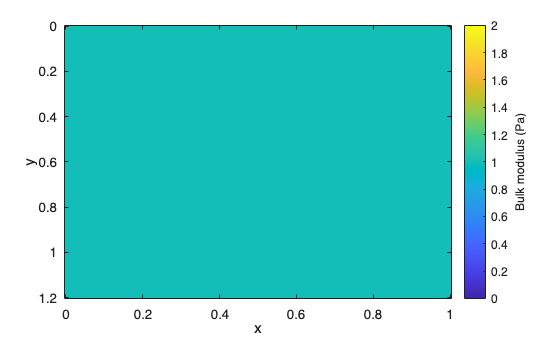

clear
close all
clc

% Computational space grids
dom_x = [0,1];
dom_y = [0,1.2];
Nx = 151;
Ny = 161;

grid_x_primal = Grid1DUnifPrimal(dom_x,Nx);
grid_y_primal = Grid1DUnifPrimal(dom_y,Ny);
grid_x_dual = Grid1DUnifDual(grid_x_primal);
grid_y_dual = Grid1DUnifDual(grid_y_primal);

gsp_P  = GridSpace2D( grid_x_primal, grid_y_primal);
gsp_Vx = GridSpace2D( grid_x_dual,   grid_y_primal);
gsp_Vy = GridSpace2D( grid_x_primal, grid_y_dual);

% Medium parameters
medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
[kappa,betax,betay,wspeed,cMax] = sampleMedium2D(gsp_P,medium);

kappa.plot;

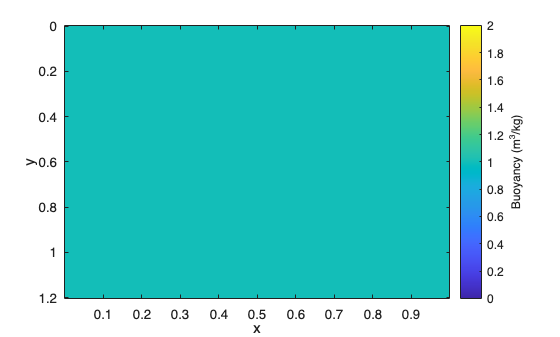

betax.plot;

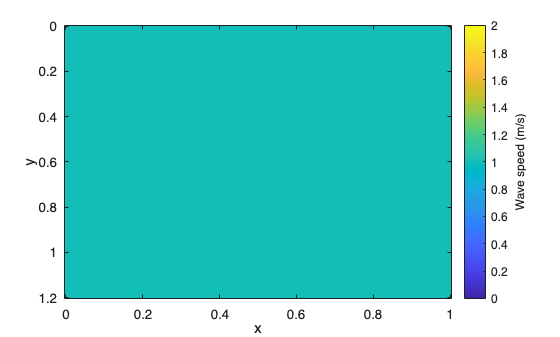

wspeed.plot;


% Computational time grid
dom_t = [0,1];
CFL = 0.9;
dt = CFL*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2)));
Nt = ceil(diff(dom_t)/dt)+1;
dt = diff(dom_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = dom_t(1):dt:dom_t(2);

% Multipole point source
src_c = [0.35,0.45];
tc = 0.2;

monopole = MultipoleTerm2D( ...
    src_c,[0,0], ...
    @(t) exp(-((tc)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

dipoleX = MultipoleTerm2D( ...
    src_c,[1,0], ...
    @(t) RickerWave(t,tc,10), ...
    Amplitude=gsp_P.h(1), ...
    TargetField="pressure");

multipole = MultipoleSeries2D( ...
    [monopole,dipoleX], ...
    ApproximationOrder=4);
source = multipole.discretize(gsp_P,gsp_Vx,gsp_Vy);

% Initializing PML
pml = PML2D( ...
    WidthLeft=0.15, ...
    WidthRight=0.15, ...
    WidthBottom=0.15, ...
    WidthTop=0.15, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Zero initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Output times
times_out = linspace(dom_t(1),dom_t(2),81);

% Defining grids consisting of points or lines to later construct grid
% spaces for different output configurations
grid_x_pt = Grid1D(dom_x,0.33);
grid_y_pt = Grid1D(dom_y,0.43);
grid_x_line = Grid1DUnifPrimal([0,0.5],11);
grid_y_line = Grid1DUnifPrimal([0.2,0.4],3);

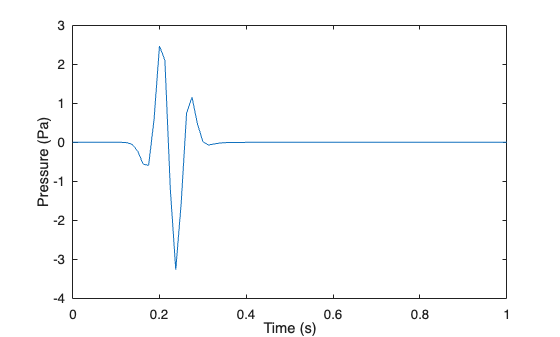

% Case with a single receiver
gsp_single = GridSpace2D(grid_x_pt,grid_y_pt);

% Initialize solver
solver_single = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_single,times_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_single,~,~] = solver_single.solve(p0,vx0,vy0,Source=source);

% Plotting results
P_single.plotTimeSeries;

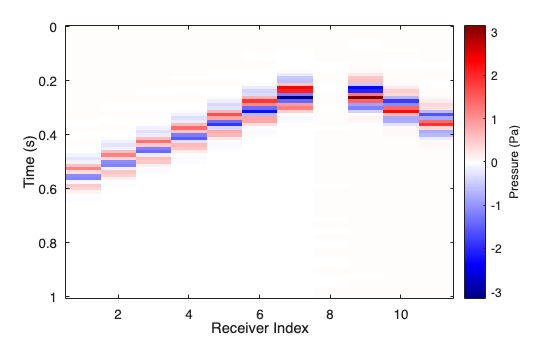

% Case with a horizontal line of receivers
gsp_x_line = GridSpace2D(grid_x_line,grid_y_pt);

% Initialize solver
solver_x_line = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_x_line,times_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_x_line,~,~] = solver_x_line.solve(p0,vx0,vy0,Source=source);

% Plotting results
P_x_line.plotTimeSeries;

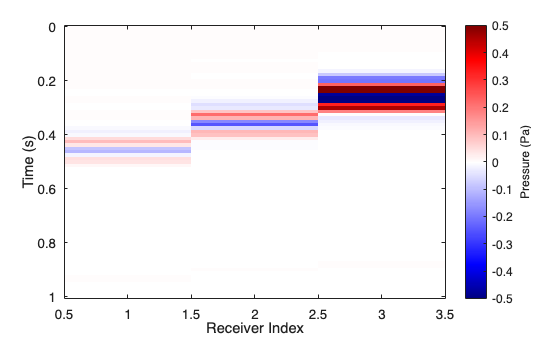

% Case with a horizontal line of receivers
gsp_y_line = GridSpace2D(grid_x_pt,grid_y_line);

% Initialize solver
solver_y_line = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_y_line,times_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_y_line,~,~] = solver_y_line.solve(p0,vx0,vy0,Source=source);

% Plotting results
ax = axes(figure);
P_y_line.plotTimeSeries(Parent=ax);
ax.CLim = [-0.5,0.5];

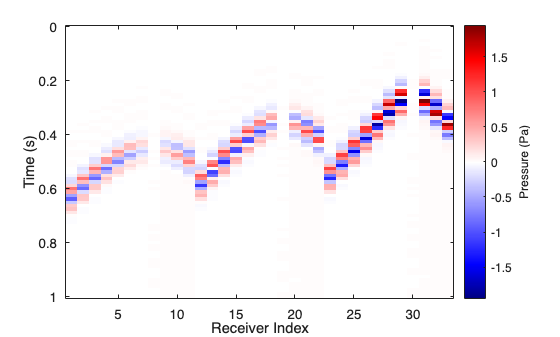

% Case with grid of receivers
gsp_grid = GridSpace2D(grid_x_line,grid_y_line);

% Initialize solver
solver_grid = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_grid,times_out, ...
    medium,pml, ...
    SpatialOrder=4);

% Run solver
[P_grid,~,~] = solver_grid.solve(p0,vx0,vy0,Source=source);

% Plotting results
P_grid.plotTimeSeries;